# **	Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Patricia Cuesta Ruiz y Laura Mambrilla Moreno**

**Fecha:**

clc;
clear all;
close all;

# Tema 4. Ejercicio 4 - Momentos

En esta práctica se trabajará con los momentos generales, centrales y de Hu como características para describir un objeto. Las funciones para calcularlos se proporcionan con este enunciado.

Se utilizarán ejemplos para comprobar, para cada uno de los momentos, su invarianza o no a traslaciones, rotaciones y homotecias, y su capacidad para discriminar objetos diferentes entre sí.

A continuación, se generarán distintas versiones de un objeto a partir de una imagen inicial, para a continuación, realizar las pruebas correspondientes. En la generación de las distintas versiones de la imagen puede haber alguna pequeña diferencia (por ejemplo, debido a la interpolación en las imágenes con rotación) que puede influir en los resultados de los cálculos. Por esta razón, se considerará que los momentos son invariantes aunque no sean exactamente iguales, si la variación es muy pequeña (en los últimos decimales).

Paso 1) Leer imagen:

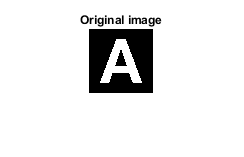

% Read original image.
IA = imread('A.jpg');

if size(IA,3) == 3 % compara si la imagen tiene tres dimensiones (imagen rbg)
    IA = rgb2gray(IA);
end
IA = imbinarize(IA);
IA = imcomplement(IA);

imshow(IA);
title('Original image');

Paso 2) Realización de la traslación, escalado y giro de la imagen inicial.

Translación

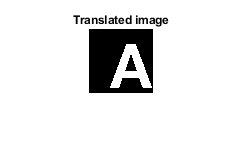

tx = 10; % x translation
ty = 5; % y translation
IA_t = imtranslate(IA,[tx, ty]); % Translated image

figure,
imshow(IA_t)
title('Translated image');

Escalado:

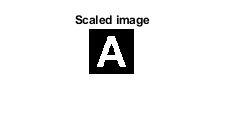

scale = 0.7; % scale factor.
IA_s = imresize(IA, scale); % scaled image
figure,
imshow(IA_s)
title('Scaled image');

Giro:

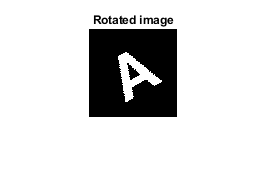

theta = 30; % the angle, theta.
IA_r = imrotate(IA,theta); % rotated A image

figure,
imshow(IA_r)
title('Rotated image');

Traslación, escalado y giro:

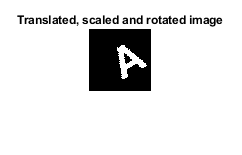

IA_ts = imresize(IA_t, scale); % Translated and scaled A image
IA_tsr = imrotate(IA_ts,theta);% Translated, scaled and rotated A image
figure,
imshow(IA_tsr)
title('Translated, scaled and rotated image');

Se pide:

- Calcule y muestre los valores de los momentos generales hasta el 1er orden (m00, m01, m10 y m11) de la imagen original (`IA`) y la imagen transladada (`IA_t`). Utilice la función `general_moments`. ¿Los valores de los momentos son iguales para las dos imágenes? ¿Se pueden considerar estos momentos invariantes a la translación? Calcule los centroides a partir de los momentos y dibújelos en las imágenes.

mom_IA = general_moments(IA, 1)

mom_IA =          841       27381
       29285      953659


mom_IA_t = general_moments(IA_t, 1)

mom_IA_t =          841       35791
       33490     1425464


**Los valores de los momentos de la imagen son diferentes, ya que los momentos generales no son invariantes a escalados, giros y traslaciones.**

         2. Calcule y muestre los valores de los momentos centrales hasta el primer orden de la imagen original (`IA`), la imagen transladada (`IA_t`) y la imagen rotada (`IA_r`). Utilice la función `central_moments`. ¿Son estos momentos invariantes a la translación? ¿y a la rotación?

         3. Calcule y muestre los valores de los momentos de Hu de la imagen original (`IA`), la imagen transladada (`IA_t)`, la imagen escalada (`IA_s),` la imagen rotada (`IA_r`) y la imagen transladada, escalada y girada (`IA_tsr`). Utilice la función `hu_moments`. ¿Son estos momentos invariantes a los cambios de escala, a la translación y a la rotación?

         4. Carge la imagen `'B.jpg'`, genere sus versiones girada, desplazada, escalada, y la imagen con las tres modificaciones y calcule y muestre los momentos de Hu de todas las versiones. ¿Son iguales para todas las versiones de B? 

         5. Compare con los momentos de Hu obtenidos para la imagen `'A.jpg'` y `'B.jpg' `¿Son iguales o diferentes? ¿Considera que podrían utilizarse para identificar objetos iguales en etapas posteriores de un sistema de visión artificial? 